## Corr_len_cal

Find correlation length scale from measurement 

- 1-D transects

-  2-D plane

- 2-D, separated between zonal and meridional directions

Assumption 

- Stationary

- Intrinsic

-  Isotropic

clear
close all

Load an tx rx file: October 2018 (HEM)

[tx_t,tx_lon,tx_lat,tx_heading,tx_altitude,tx_xvel,range,x_err,y_err,z_err,act_arrival,est_arrival,SNR] = tx_rx_extraction_Oct(27:30,3,14,'HEM');
tx_lat_HEM = tx_lat;
tx_lon_HEM = tx_lon;
d_HEM = (act_arrival-est_arrival)*3600*24;

Load an tx rx file: June 2017 (HEM)

[tx_t,tx_lon,tx_lat,tx_heading,tx_altitude,tx_xvel,range,x_err,y_err,z_err,act_arrival,est_arrival,SNR] = tx_rx_extraction_June2017(7:12,13,5);
tx_lat_HEM2= tx_lat;
tx_lon_HEM2= tx_lon;
d_HEM2 = (act_arrival-est_arrival)*3600*24;


Load an tx rx file: October 2018 (icListen)

[tx_t,tx_lon,tx_lat,tx_heading,tx_altitude,tx_xvel,range,x_err,y_err,z_err,act_arrival,est_arrival,SNR] = tx_rx_extraction_Oct(27:30,3,14,'icListen');
tx_lat_ic= tx_lat;
tx_lon_ic= tx_lon;
d_ic= (act_arrival-est_arrival)*3600*24;

Plot travel times perturbation measurements

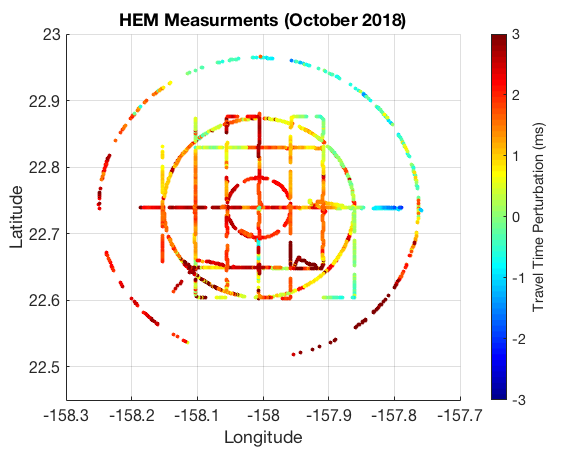


f1 = figure(1);
s1 = scatter(tx_lon_HEM,tx_lat_HEM);
color_range = [-3 3];
fpos = [0 0.2];
plot_RAP_txmap(f1,s1,'HEM Measurments (October 2018)',color_range,d_HEM,fpos);

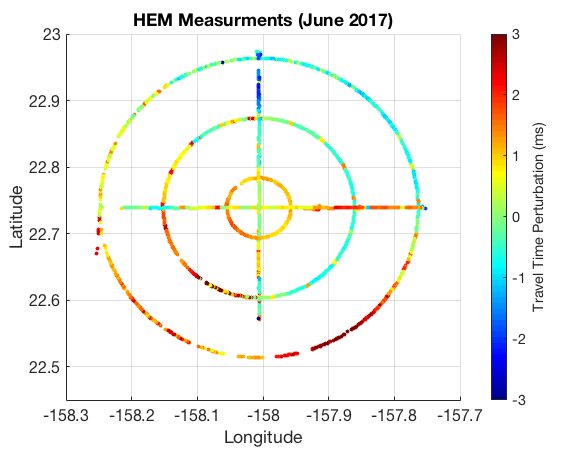


f1 = figure(2);
s1 = scatter(tx_lon_HEM2,tx_lat_HEM2);
color_range = [-3 3];
fpos = [0.4 0.2];
plot_RAP_txmap(f1,s1,'HEM Measurments (June 2017)',color_range,d_HEM2,fpos);

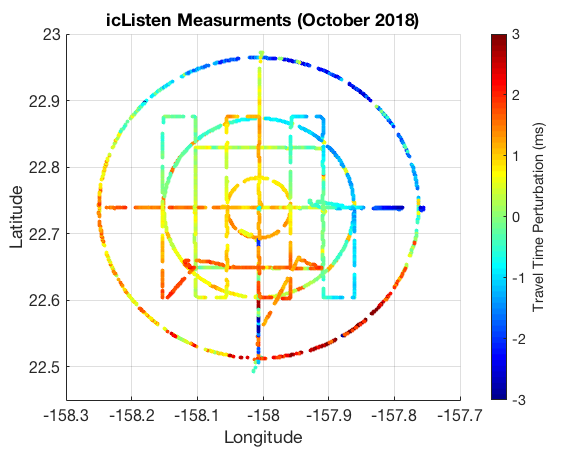


f2 = figure(3);
s2 = scatter(tx_lon_ic,tx_lat_ic);
color_range = [-3 3];
fpos = [0.6 0.2];
plot_RAP_txmap(f2,s2,'icListen Measurments (October 2018)',color_range,d_ic,fpos);

**Set up transects** 

Lat = 22.73-22.75

Lon = -157.8 – -158.30

L = resampling data factor (downsampling)

**HEM **

**October 2018**

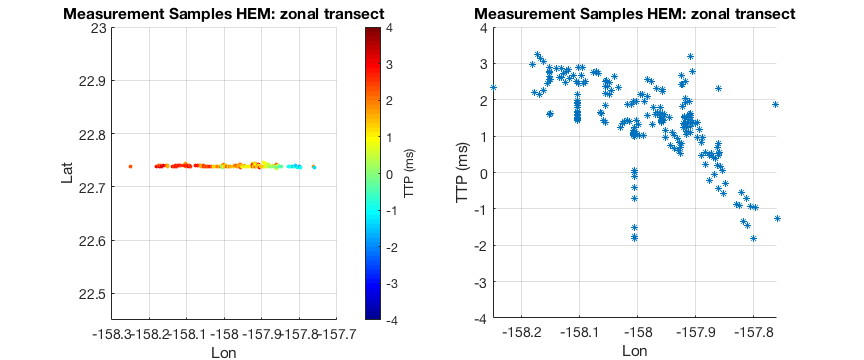

% 1. zonal
L = 5;  % downsampling factor
lat_range = [22.735 22.745];
lon_range = [-158.3 -157.7];
[ttp_HEMz_Oct2018,tx_lat_HEMz_Oct2018,tx_lon_HEMz_Oct2018] = select_sample(d_HEM,tx_lat_HEM,tx_lon_HEM,lat_range,lon_range,L,'lat');

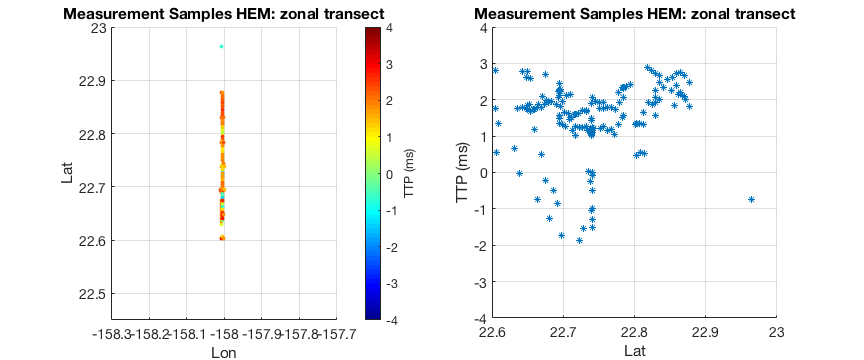

% 2. meridional
L = 4;  % downsampling factor
lat_range = [22.48 23];
lon_range = [-158.01 -158];
[ttp_HEMm_Oct2018,tx_lat_HEMm_Oct2018,tx_lon_HEMm_Oct2018] = select_sample(d_HEM,tx_lat_HEM,tx_lon_HEM,lat_range,lon_range,L,'lon');

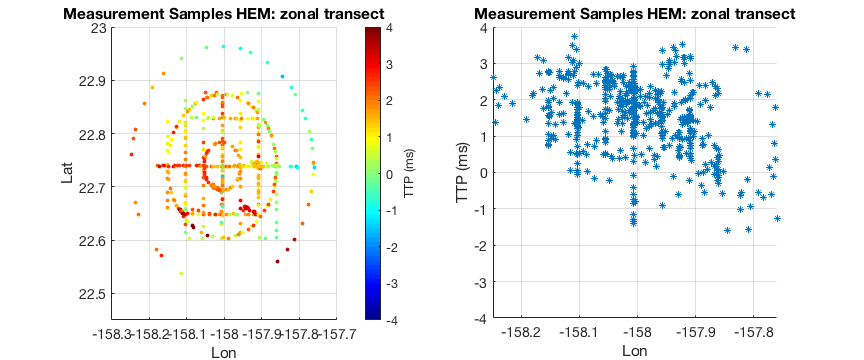


% 3. 2-D
L = 10;  % downsampling factor
lat_range = [22.48 23];
lon_range = [-158.3 -157.7];
[ttp_HEM_2D_Oct2018,tx_lat_HEM_2D_Oct2018,tx_lon_HEM_2D_Oct2018] = select_sample(d_HEM,tx_lat_HEM,tx_lon_HEM,lat_range,lon_range,L,'lat');

**June 2017**

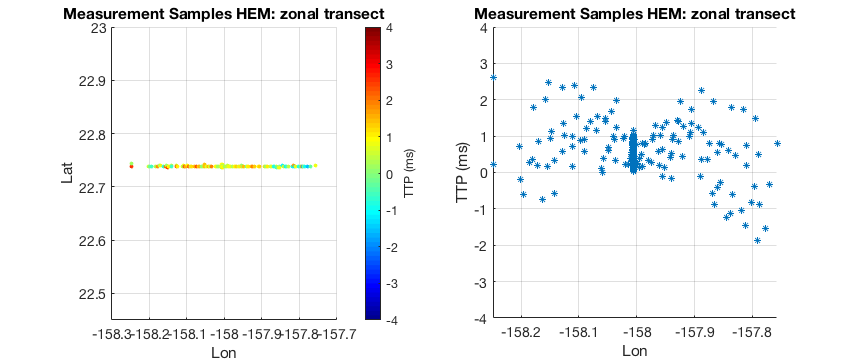

% 1. zonal
L = 14;  % downsampling factor
lat_range = [22.735 22.745];
lon_range = [-158.3 -157.7];
[ttp_HEMz_June2017,tx_lat_HEMz_June2017,tx_lon_HEMz_June2017] = select_sample(d_HEM2,tx_lat_HEM2,tx_lon_HEM2,lat_range,lon_range,L,'lat');

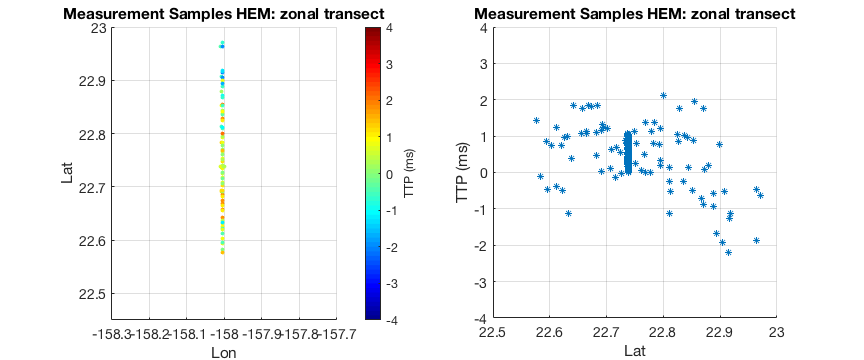

% 2. meridional
L = 12;  % downsampling factor
lat_range = [22.48 23];
lon_range = [-158.01 -158];
[ttp_HEMm_June2017,tx_lat_HEMm_June2017,tx_lon_HEMm_June2017] = select_sample(d_HEM2,tx_lat_HEM2,tx_lon_HEM2,lat_range,lon_range,L,'lon');

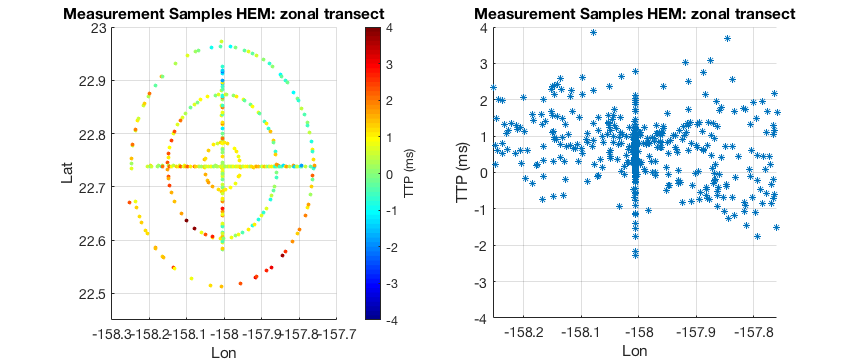


% 3. 2-D
L = 13;  % downsampling factor
lat_range = [22.48 23];
lon_range = [-158.3 -157.7];
[ttp_HEM_2D_June2017,tx_lat_HEM_2D_June2017,tx_lon_HEM_2D_June2017] = select_sample(d_HEM2,tx_lat_HEM2,tx_lon_HEM2,lat_range,lon_range,L,'lat');

**icListen**

**October 2018**

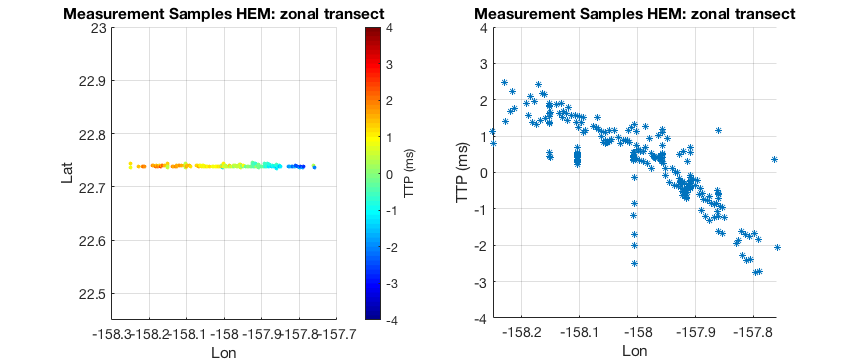

% 1. zonal
L = 5;  % downsampling factor
lat_range = [22.735 22.745];
lon_range = [-158.3 -157.7];
[ttp_ic1,tx_lat_ic1,tx_lon_ic1] = select_sample(d_ic,tx_lat_ic,tx_lon_ic,lat_range,lon_range,L,'lat');

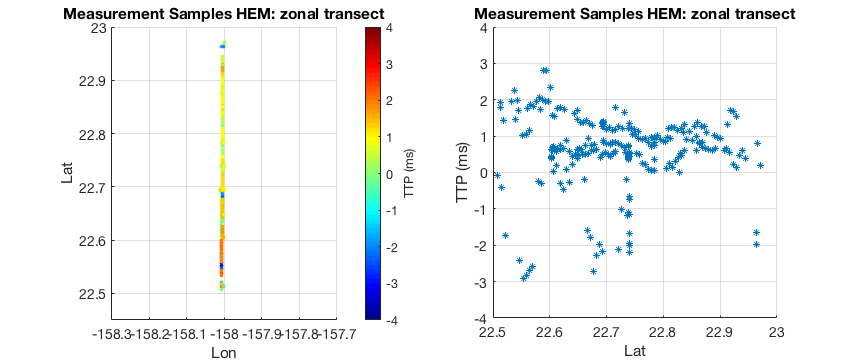

% 2. meridional
L = 4;  % downsampling factor
lat_range = [22.48 23];
lon_range = [-158.01 -158];
[ttp_ic2,tx_lat_ic2,tx_lon_ic2] = select_sample(d_ic,tx_lat_ic,tx_lon_ic,lat_range,lon_range,L,'lon');

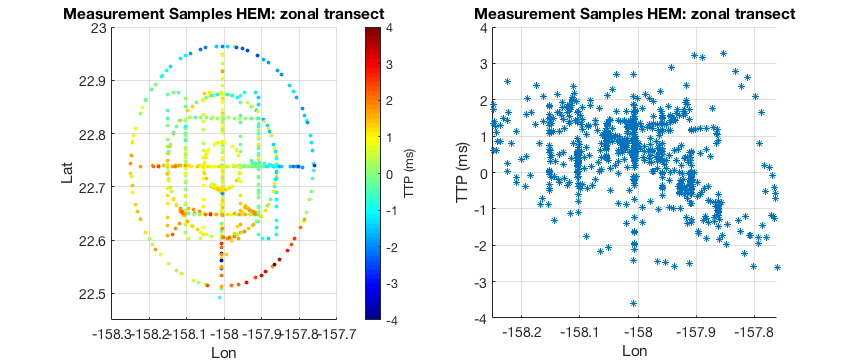


% 3. 2-D
L = 10;  % downsampling factor
lat_range = [22.48 23];
lon_range = [-158.3 -157.7];
[ttp_ic_2D,tx_lat_ic_2D,tx_lon_ic_2D] = select_sample(d_ic,tx_lat_ic,tx_lon_ic,lat_range,lon_range,L,'lat');

**Create experimental (semi)variogram** 

$\gamma(h) = \frac{1}{2N_k} \sum\limits_{i=1}^{N_k}(z(\mathbf{x}_i)-z(\mathbf{x'}_i))^2$ where


$$z \text{ = data }$$



$$N_k =\text{number of pairs}$$



$$\mathbf{x}_i = \text{position coordinates}$$


**HEM: October 2018**

sample =    215


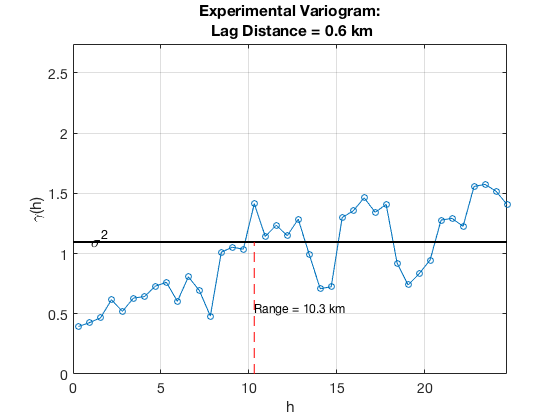

%% 1. Zonal Transect
bin_num = 80;

plot_variogram(ttp_HEMz_Oct2018,tx_lat_HEMz_Oct2018,tx_lon_HEMz_Oct2018,bin_num,'isotropic')

sample =    163


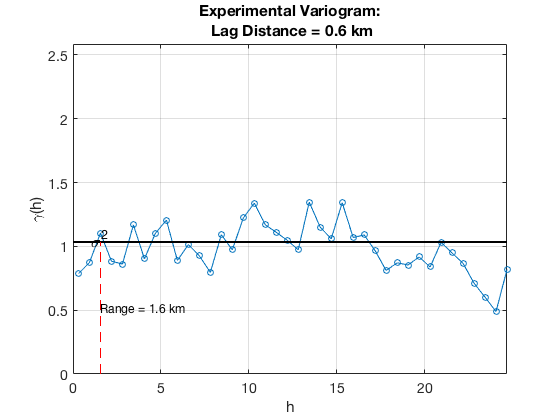


%% 2. Meridional Transect
bin_num = 80;

plot_variogram(ttp_HEMm_Oct2018,tx_lat_HEMm_Oct2018,tx_lon_HEMm_Oct2018,bin_num,'isotropic')

sample =    517


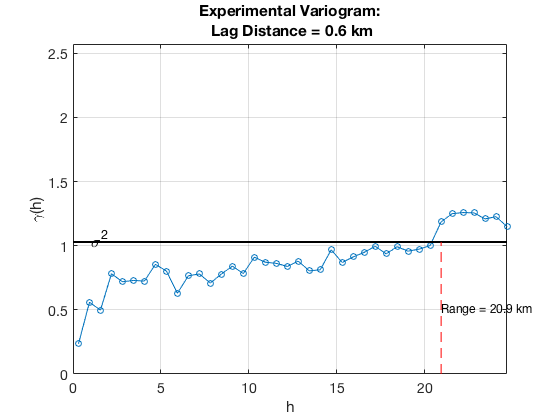


%% 3. Horizontal
bin_num = 80;

plot_variogram(ttp_HEM_2D_Oct2018,tx_lat_HEM_2D_Oct2018,tx_lon_HEM_2D_Oct2018,bin_num,'isotropic')

sample =    517


Total Pairs = 21605, All possible pairs = 133386: = 1.619735e+01 

Total Pairs = 15044, All possible pairs = 133386: = 1.127854e+01 

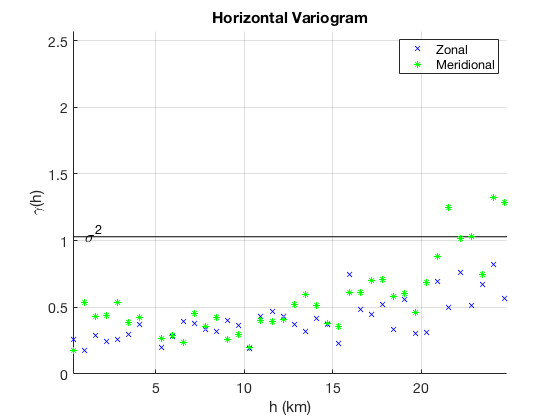

%% 4. Anisotropic
bin_num = 80;

plot_variogram(ttp_HEM_2D_Oct2018,tx_lat_HEM_2D_Oct2018,tx_lon_HEM_2D_Oct2018,bin_num,'anisotropic')

**HEM: June 2017**

sample =    416


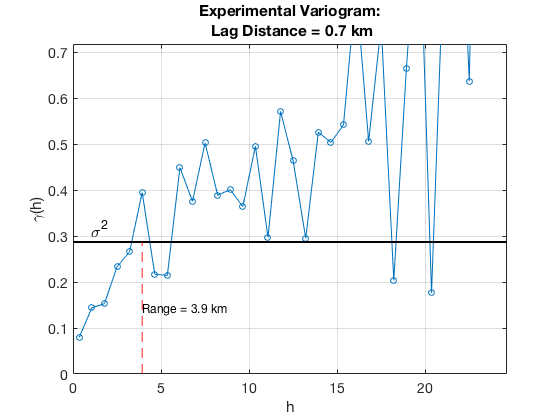

%% 1. Zonal Transect
bin_num = 70;

plot_variogram(ttp_HEMz_June2017,tx_lat_HEMz_June2017,tx_lon_HEMz_June2017,bin_num,'isotropic')

sample =    420


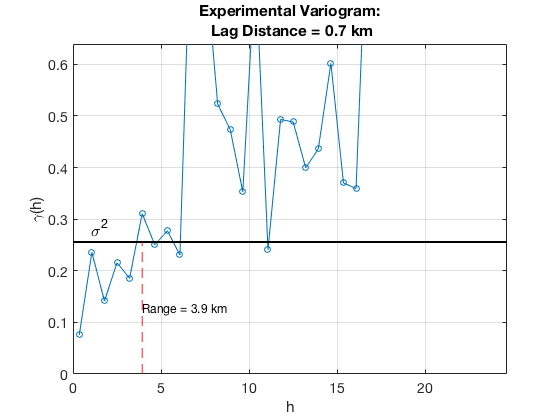


%% 2. Meridional Transect
bin_num = 70;

plot_variogram(ttp_HEMm_June2017,tx_lat_HEMm_June2017,tx_lon_HEMm_June2017,bin_num,'isotropic')

sample =    693


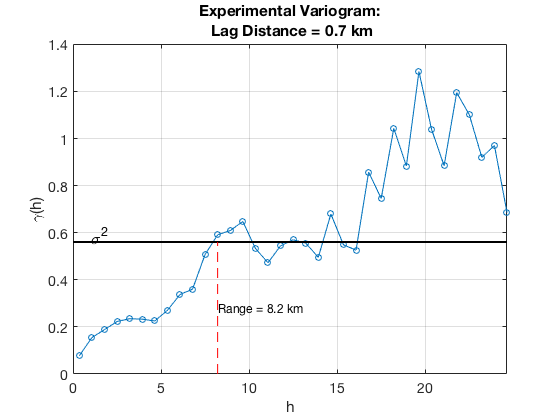


%% 3. Horizontal
bin_num = 70;

plot_variogram(ttp_HEM_2D_June2017,tx_lat_HEM_2D_June2017,tx_lon_HEM_2D_June2017,bin_num,'isotropic')

sample =    693


Total Pairs = 69422, All possible pairs = 239778: = 2.895261e+01 

Total Pairs = 48716, All possible pairs = 239778: = 2.031713e+01 

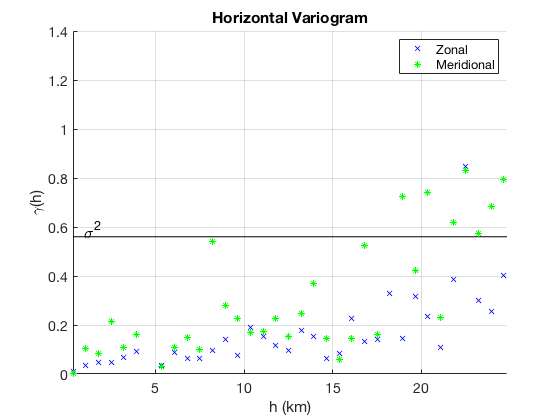


%% 4. Anisotropic
bin_num = 70;

plot_variogram(ttp_HEM_2D_June2017,tx_lat_HEM_2D_June2017,tx_lon_HEM_2D_June2017,bin_num,'anisotropic')

**icListen**

sample =    230


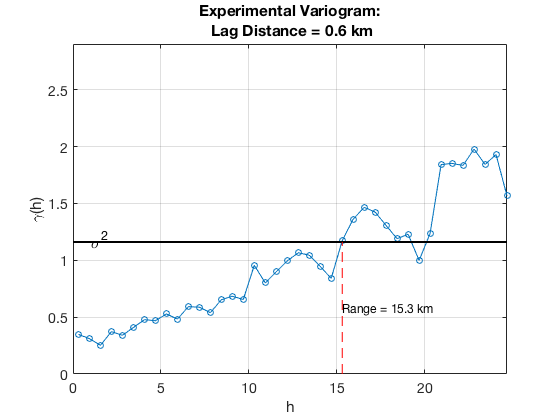

%% 1. Zonal Transect
bin_num = 80;

plot_variogram(ttp_ic1,tx_lat_ic1,tx_lon_ic1,bin_num,'isotropic')

sample =    242


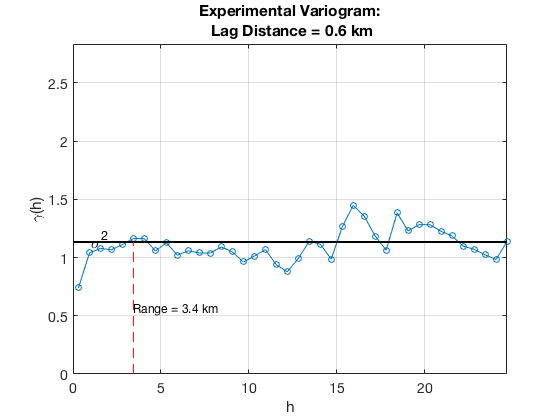


%% 2. Meridional Transect
bin_num = 80;

plot_variogram(ttp_ic2,tx_lat_ic2,tx_lon_ic2,bin_num,'isotropic')

sample =    656


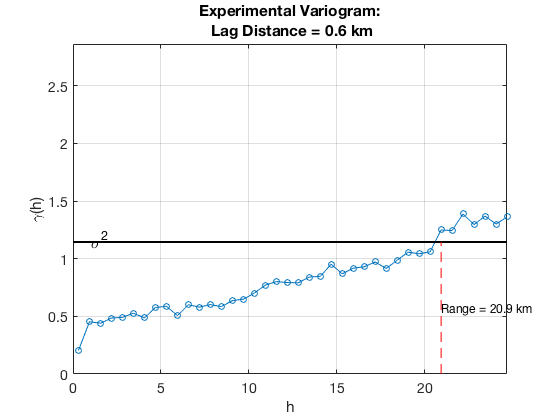


%% 3. Horizontal
bin_num = 80;

plot_variogram(ttp_ic_2D,tx_lat_ic_2D,tx_lon_ic_2D,bin_num,'isotropic')

sample =    656


Total Pairs = 28683, All possible pairs = 214840: = 1.335087e+01 

Total Pairs = 24624, All possible pairs = 214840: = 1.146155e+01 

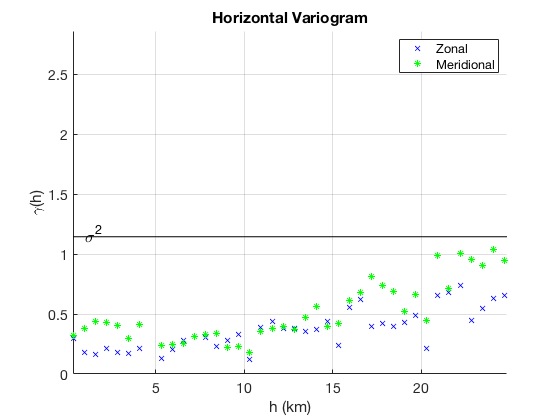

%% 4. Anisotropic
bin_num = 80;

plot_variogram(ttp_ic_2D,tx_lat_ic_2D,tx_lon_ic_2D,bin_num,'anisotropic')

## Function

1.  Select data samples

function [ttp,tx_lat_s,tx_lon_s] = select_sample(d,tx_lat,tx_lon,lat_range,lon_range,L,fixed_axis)
Llon = lon_range(1);
Ulon = lon_range(2);
Llat = lat_range(1);
Ulat = lat_range(2);

lonlim = find((tx_lon< Ulon & tx_lon > Llon)  == 1);
latlim = find((tx_lat< Ulat & tx_lat > Llat) == 1);
keep_ind = intersect(lonlim,latlim);

% resample
keep_ind = keep_ind(1:L:end);

d = d(keep_ind);
tx_lon = tx_lon(keep_ind);
tx_lat = tx_lat(keep_ind);

% sort array elements from left to right
[tx_lon_s,new_ind] = sort(tx_lon);
tx_lat_s = tx_lat(new_ind);
d = d(new_ind);
% travel time perturbation in ms
ttp = d*1000;

f3 = figure;
clf
subplot(1,2,1)
s3 = scatter(tx_lon_s,tx_lat_s);
color_range = [-4 4];
fpos = [0.1 0.6];
color_data = ttp;
set(f3,'Units','normalized','Position',[fpos 0.6 0.4])
set(s3,'Marker','o','MarkerFaceColor','flat','SizeData',10,'CData',color_data)
xlim([-158.3 -157.7])
xticks(-158.3:0.1:-157.7)
ylim([22.45 23])
grid on
xlabel('Lon')
ylabel('Lat')

cbar = colorbar;
caxis([color_range]);
colormap jet;
cbar.Label.String = 'TTP (ms)';
set(gca,'fontsize',14)
title('Measurement Samples HEM: zonal transect','fontsize',16)

subplot(1,2,2)
switch fixed_axis
    case 'lat'
        scatter(tx_lon_s,ttp,[],'*');
        xlabel('Lon')
    case 'lon'
        scatter(tx_lat_s,ttp,[],'*');
        xlabel('Lat')
end
grid on
ylabel('TTP (ms)')
ylim(color_range)
set(gca,'fontsize',14)
title('Measurement Samples HEM: zonal transect','fontsize',16)
end


2.  Variogram

Create experimental (semi)variogram

**Isotropic**

1. In the outer loop, fix the head point, starting from the western end to the eastern end.

2. In the inner loop, loop over data points located to the east of the head point. Calculate separation distance and assign a lag bin in which the separation distance lies.

3. Calculate raw variogram. Add gamma value to the assigned bin (*gamma*). Count the number of pairs fall into each bin (*Nk*)

4. Add gamma value vector to the total *ex_gamma* vector at the end of each head point loop

5. Average each bin of *ex_gamma *by its corresponding number of pairs 

**Anisotropic**

1.  Set up 2 horizontal major and minor axes (now zonal and meridional axes)

2.  Set up search pattern reference illustration: [http://geostatisticslessons.com/lessons/variogramparameters](http://geostatisticslessons.com/lessons/variogramparameters)

3.  Loop over all samples. Start with fixing a head sample of each loop.

4   After fixing a head sample, loop over all lag bins. Search for all tail possible tail samples fall into the current lag bin.

5. Use azimuth tolerance criterion to eliminate outside tail samples

6. Use bandwidth criterion to eliminate outside tail samples

7. Check if the pair of the head and tail samples has been used in the previous loops

8.  When paired, record the indices of paired data points (avoiding using redundant data pairs)

9. After calculating all raw variogram, average each gamma value by its corresponding number of pairs

10. repeat the same process but on the other principal axis    

function plot_variogram(ttp,tx_lat,tx_lon,bin_num,type)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
sill = var(ttp);

switch type
    case 'isotropic'
        sample = length(ttp)
        all_Nk = sample*(sample-1)/2;   % gamma data points
        
        % lag bins
        lag_distance = 50000/bin_num;           % meter
        lag_bin = [0:bin_num-1]*lag_distance+lag_distance/2;
        
        ex_gamma = zeros(1,length(lag_bin));         % experimental gamma
        Nk = zeros(1,length(lag_bin));
        % loop over pairs of measurements
        for ii = 1:sample
            % 1st data point
            lon_head = tx_lon(ii);
            lat_head = tx_lat(ii);
            gamma = zeros(1,length(lag_bin));
            for jj = ii:sample   % from iith data point to the last data point
                % 2nd data point
                % calculate 
                % 1. separation 
                [separation,~] = distance(lat_head,lon_head,tx_lat(jj),tx_lon(jj),referenceEllipsoid('WGS84'));
                
                % categorize lag bin
                [~,bin] = min(abs(separation-lag_bin));
                Nk(bin) = Nk(bin)+1;
                
                % raw variogram
                gamma(bin) = gamma(bin) + 0.5*(ttp(ii) - ttp(jj))^2;
                
            end
            ex_gamma = ex_gamma+gamma;
            
        end
        % average ex_gamma
        ex_gamma = ex_gamma./(Nk);
          
        % domain size
        domain_size = (max(lag_bin)-min(lag_bin))/1000;
        % range
        range_ind = find(ex_gamma>sill,1,'first');
        
        range = lag_bin(range_ind)/1000;
        
        f1 = figure;
        p1 =  plot(lag_bin/1000,ex_gamma,'Linewidth',1,'Marker','o');
        grid on
        xlabel('h')
        ylabel('\gamma(h)')
        xlim([0 domain_size/2])             % limit to 1/2 domain size
        ylim([0 2.5*sill])
        title(sprintf('Experimental Variogram:\n Lag Distance = %.1f km',lag_distance/1000))
        set(gca,'fontsize',14)
        hold on
        % plot sill
        line([0 max(lag_bin/1000)],[sill sill],'Color','k','LineWidth',2)
        % plot range
        line([range range],[0 sill],'Color','r','LineStyle','--')
        text(range,sill/2,sprintf('Range = %.1f km',range),'FontSize',12)
        text(1,sill+0.03,'\sigma^{2}','fontsize',16)
        
    case 'anisotropic'
        % 1. zonal (Easting)
        sample = length(ttp)
        
        % search pattern
        azmth = 90;
        azmth_tol = 30;
        lag_distance = 50000/bin_num;           % meter
        % lag bins
        lag_bin = [0:bin_num-1]*lag_distance+lag_distance/2;
        
        bandwidth = 5000;                     % meter
        
        % loop over pairs of measurements
        [ex_gamma_zonal,Nk_zonal] = pairing(sample,ttp,tx_lat,tx_lon,lag_bin,bin_num,bandwidth,azmth,azmth_tol);
        % Plot Zonal Variogram
        ex_gamma_zonal = sum(ex_gamma_zonal)./sum(Nk_zonal);
        
        figure;
        
        s1 = scatter(lag_bin/1000,ex_gamma_zonal,'xb');
        hold on
        line([lag_bin(1) lag_bin(end)]./1000,[sill sill],'Color','black')
        ylim([0 2.5*sill])
        xlim([min(lag_bin)/1000 max(lag_bin)/1000*0.5])
        grid on
        xlabel('h (km)')
        ylabel('\gamma(h)')
        legend('Zonal')
        var_az = gca;
        text(1,sill+0.03,'\sigma^{2}','fontsize',16)
        
        % 2. Meridional (Northing)
        % search pattern
        azmth = 0;
        azmth_tol = 30;
        lag_distance = 50000/bin_num;           % meter
        % lag bins
        lag_bin = [0:bin_num-1]*lag_distance+lag_distance/2;
        
        bandwidth = 5000;                     % meter
        
        % loop over pairs of measurements
       [ex_gamma_merdional,Nk_meridional] = pairing(sample,ttp,tx_lat,tx_lon,lag_bin,bin_num,bandwidth,azmth,azmth_tol);
        
        % Plot Zonal Variogram
        ex_gamma_merdional = sum(ex_gamma_merdional)./sum(Nk_meridional);
        
        hold on
        s2 = scatter(var_az,lag_bin/1000,ex_gamma_merdional,'*g');
        legend([s1,s2],{'Zonal','Meridional'})
        set(gca,'FontSize',14)
        title('Horizontal Variogram')
        
        
%         cd /Users/testuser/Documents/ONR_RAP/Data
%         fname = "variogram_"+num2str(sample)
%         save(fname,'lag_bin','ex_gamma_zonal','ex_gamma_merdional');
        
        
end % switch
end


3. pairing

function  [ex_variogram,Nk] = pairing(sample,ttp,tx_lat,tx_lon,lag_bin,bin_num,bandwidth,azmth,azmth_tol)
    % initialize parameters
    ex_variogram = zeros(sample,bin_num);      % pre-allocate-space experimental gamma
    Nk = zeros(sample,bin_num);                % total piars of each lag bin
    paired_num = [];                           % paired data point
   
for ii = 1:sample
      
    % 1st data point coordinate
    lon_head = tx_lon(ii);
    lat_head = tx_lat(ii);
    [east_head,north_head,utmzone] = deg2utm(lat_head,lon_head);
    
    % define searching domain
    % lon/lag coordinates from lag_bin+azimuth
    [lon_bin,lat_bin,~] = m_fdist(lon_head*ones(1,length(lag_bin)),lat_head*ones(1,length(lag_bin)),azmth*ones(1,length(lag_bin)),lag_bin);
    lon_bin = lon_bin-360;
    coord_bin = [lon_bin' lat_bin'];
    [east_bin,north_bin,~] = deg2utm(lat_bin,lon_bin);
    
    % limiting coordinates
    lim_r =  bandwidth/2/sin(azmth_tol/180*pi); % meter
    [lim_lonu,lim_latu,~] = m_fdist(lon_head,lat_head,azmth-azmth_tol,lim_r);
    [lim_lonl,lim_latl,~] = m_fdist(lon_head,lat_head,azmth+azmth_tol,lim_r);
    lim_lon = [lim_lonl lim_lonu]-360;
    lim_lat = [lim_latl lim_latu];
    [east_lim,north_lim,~] = deg2utm(lim_lat,lim_lon);
    
    % visualize the search pattern
    %{
    figure(1);
    clf
    set(gcf,'Units','normalized','Position',[0 0.5 0.35 0.4])
    hold on
    scatter(lon_head,lat_head,'black','filled')
    hold on
    scatter(lon_bin,lat_bin,'bx')
    scatter(lim_lon,lim_lat,'rx')
    line([lon_head lim_lon(1)],[lat_head lim_lat(1)],'Color','red')
    line([lon_head lim_lon(2)],[lat_head lim_lat(2)],'Color','red')
    xlim([-158.3 -157.7])
    xticks(-158.3:0.1:-157.7)
    ylim([22.45 23])
    grid on
    %}
    
    % define search zone 1 and 2
    % zone 1
    mid_point = [mean(east_lim) mean(north_lim)];
    ind_xeast = find(mid_point(1)>east_bin,1,'last');
    ind_xnorth = find(mid_point(2)>north_bin,1,'last');
    
    % define the lag bin at which the zone transiion occurs
    if ind_xeast < ind_xnorth
        ind_x = ind_xeast;
    else
        ind_x = ind_xnorth;
    end
    
    % zone 2
    % define limitng line equation
    slope = cotd(azmth);
    if isinf(slope)
        % meridional line
        intercept =  east_lim;
        
    else
        intercept = [north_lim(1)-slope*east_lim(1) ,...
            north_lim(2)-slope*east_lim(2)];
        
    end
    
    %%%%%%%%%%%%%%%%%% loop over tail sameples %%%%%%%%%%%%%%%%%%
    % search for all data points
    paired_num_now = [];
    % circle search
    dist_all = distance(lat_head*ones(1,size(tx_lat,2)),lon_head*ones(1,size(tx_lat,2)),tx_lat,tx_lon,referenceEllipsoid('WGS84'));
    
    % zone 1
    for bin = 1:ind_x
        % extract indices of samples fall into this bin
        keep_ind = [];
        
        % check range
        if bin ==1
            keep_ind = find(dist_all < lag_bin(1));
        else
            keep_ind = find((dist_all >= lag_bin(bin-1))&(dist_all < lag_bin(bin)));
        end
        keep_ind(find(keep_ind == ii)) = []; % remove the head data point
        
        % check if paired
        k_len = length(keep_ind);
        if ~isempty(keep_ind)
            paired_num_now = [ii*ones(k_len,1) keep_ind'];
        else
            paired_num_now = [];
        end
        
        % remove paired data points
        if ~isempty(paired_num_now)
            [~,~,redundant_pair_ind] = intersect(flip(paired_num,2),paired_num_now,'row');
        else
            redundant_pair_ind = [];
        end
        keep_ind(redundant_pair_ind) = [];
        
        % check angle limit
        [~,az_tail] = distance(lat_head*ones(1,length(keep_ind)),...
            lon_head*ones(1,length(keep_ind)),...
            tx_lat(keep_ind),tx_lon(keep_ind),referenceEllipsoid('WGS84'));
        
        rm_keep_ind = (az_tail <= azmth-azmth_tol) |  (az_tail >= azmth+azmth_tol);
        keep_ind(rm_keep_ind) = [];     % remove data points outside the angular zone
        
        % save paired data points
        k_len = length(keep_ind);
        paired_num_now = [ii*ones(k_len,1) keep_ind'];
        paired_num = vertcat(paired_num,paired_num_now);
        
        % cal ex variogram for the current bin
        
        if ~isempty(keep_ind)
            Nk(ii,bin) = length(keep_ind);
            ex_variogram(ii,bin) =  0.5/Nk(ii,bin)*sum((ttp(ii)-ttp(keep_ind)).^2);
            
        else
            ex_variogram(ii,bin) = 0;
            Nk(ii,bin) = 0;
            
        end
    end
    
    
    % zone 2
    for bin = ind_x+1:length(lag_bin)
        if bin == ind_x+1   % transition
            % zone 1
            keep_ind = find((dist_all < lim_r) & (dist_all >= lag_bin(ind_x)));
            % check angle limit
            [~,az_tail] = distance(lat_head*ones(1,length(keep_ind)),...
                lon_head*ones(1,length(keep_ind)),...
                tx_lat(keep_ind),tx_lon(keep_ind),referenceEllipsoid('WGS84'));
            
            rm_keep_ind = (az_tail <= azmth-azmth_tol) |  (az_tail >= azmth+azmth_tol);
            keep_ind(rm_keep_ind) = [];
            
            % zone 2
            keep_ind = find((dist_all < lag_bin(ind_x+1)) & (dist_all >= lim_r));
            
            
        else
            keep_ind = find((dist_all >= lag_bin(bin-1))&(dist_all < lag_bin(bin)));
        end
        
        % check if paired
        k_len = length(keep_ind);
        if ~isempty(keep_ind)
            paired_num_now = [ii*ones(k_len,1) keep_ind'];
        else
            paired_num_now = [];
        end
        % remove paired data points
        if ~isempty(paired_num_now)
            [~,~,redundant_pair_ind] = intersect(flip(paired_num,2),paired_num_now,'row');
        else
            redundant_pair_ind = [];
        end
        keep_ind(redundant_pair_ind) = [];
        
        
        % check band limit
        if ~isempty(keep_ind)
            % Work in UTM
            if ~isinf(slope)
                [east_sample,north_sample,~] = deg2utm(tx_lat(keep_ind),tx_lon(keep_ind));
                intercept_sample = north_sample-slope*east_sample;
                rm_keep_ind = find((intercept_sample < min(intercept))|(intercept_sample > max(intercept)));
            else
                [east_sample,north_sample,~] = deg2utm(tx_lat(keep_ind),tx_lon(keep_ind));
                rm_keep_ind = find((east_sample < min(intercept))|(east_sample > max(intercept)));
            end
        else
            rm_keep_ind  = [];
        end
        keep_ind(rm_keep_ind) = [];
        
        % save paired data points
        k_len = length(keep_ind);
        paired_num_now = [ii*ones(k_len,1) keep_ind'];
        paired_num = vertcat(paired_num,paired_num_now);
        
        % cal ex variogram
        if ~isempty(keep_ind)
            Nk(ii,bin) = length(keep_ind);
            ex_variogram(ii,bin) =  0.5/Nk(ii,bin)*sum((ttp(ii)-ttp(keep_ind)).^2);
        else
            ex_variogram(ii,bin) = 0;
            Nk(ii,bin) = 0;
            
        end
        
    end
    %{
    figure(1)
    hold on
    scatter(tx_lon((paired_num(:,2))),tx_lat(paired_num(:,2)),'ok')
    %}
end % for all samples
fprintf('Total Pairs = %d, All possible pairs = %d: = %d %',length(paired_num),sample*(sample-1)/2,length(paired_num)/(sample*(sample-1)/2)*100);

end